# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.3 单独设置子图的colormap

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

思路：绘图时设置的 colormap 默认都是针对整个 figure 的，如需用不同的颜色需要单独再设置 colormap 属性。

也有一个开源函数 freezeColors 可用，链接如下：

[https://ww2.mathworks.cn/matlabcentral/fileexchange/7943-freezecolors-unfreezecolors](https://ww2.mathworks.cn/matlabcentral/fileexchange/7943-freezecolors-unfreezecolors)

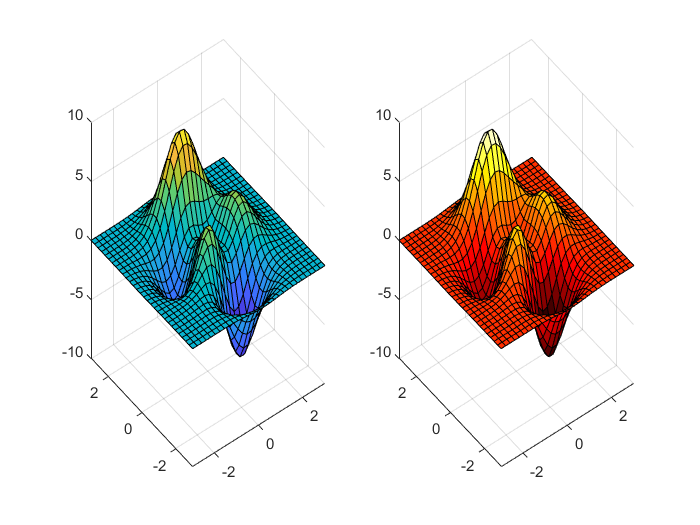

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
[x, y, z] = peaks(30);
figure;
plot1 = subplot(1,2,1);
surf(x, y, z);
% 获取第一幅图的 colormap，默认为 parula
cMap = colormap;
plot2 = subplot(1,2,2);
surf(x, y, z);
% 下面设置的是第二幅图的颜色，默认是整个 figure 的
colormap(hot);
% 设置第一幅图颜色显示为 parula
set(plot1, 'Colormap', cMap);

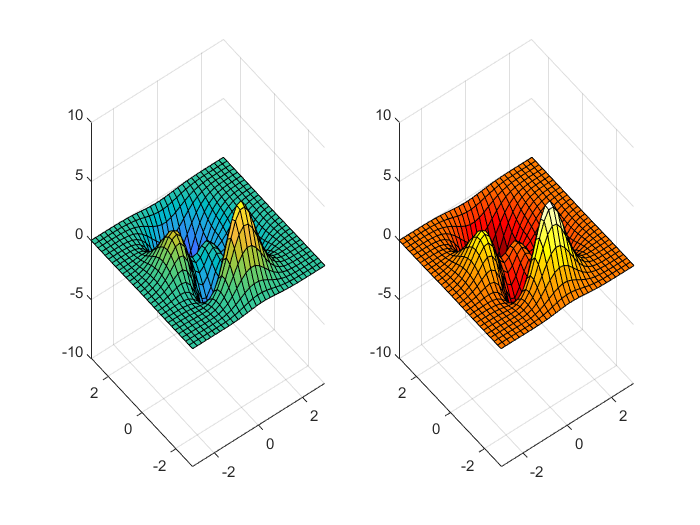

% 用 freezeColors 方法
figure;
subplot(1,2,1);
surf(x, y, -z);
freezeColors;
subplot(1,2,2);
surf(x, y, -z);
colormap(hot);

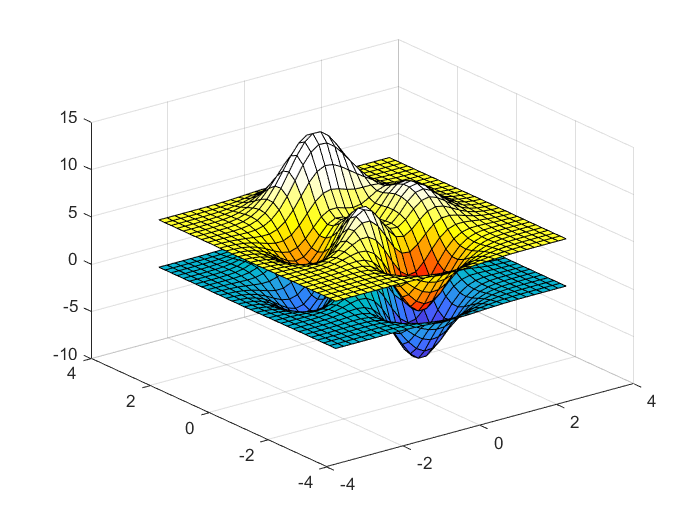

% 一个坐标轴
figure;
h1 = surf(x, y, z);
freezeColors;
hold on
h2 = surf(x, y, z + 5);
hold off
colormap(hot);

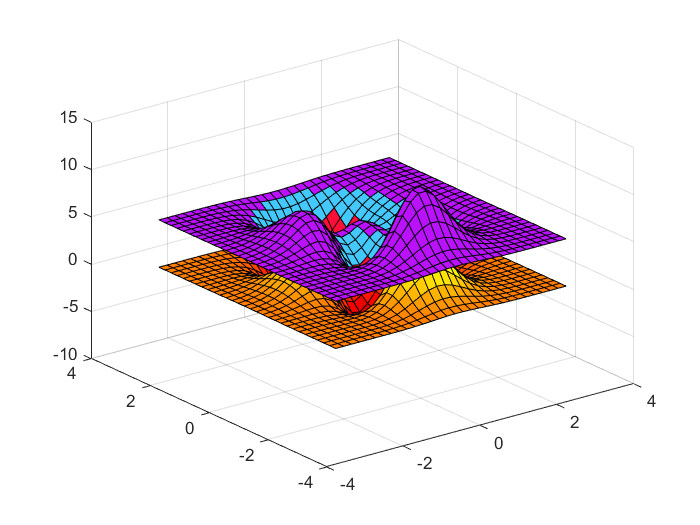

% 读取本地的 figure 文件进行二次编辑
fig = openfig('data\MultiColormap.fig');
cmap = fig.Colormap;
% 多个子图
cmap1 = fig.Children(1).Colormap;
cmap2 = fig.Children(2).Colormap;
% 数据 figure --> axes --> plot
% ax = get(gcf, 'Children');
% plt = get(gca, 'Children');
x = fig.Children(2).Children(1).XData;
y = fig.Children(2).Children(1).YData;
z = fig.Children(2).Children(1).ZData;
figure;
surf(x, y, z);
colormap(cmap1);
freezeColors;
hold on
surf(x, y, z + 5);
hold off
colormap(all_themes{4});